# Cardiac_Day21 test

## small tile

run_id = 'test';

input_path = 'F:/2020-09-14-Cardiac-Day21/';
useGPU = true;


data_dirs = dir(fullfile(input_path, "round1", "position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name)

data_dirs = 74×1 cell array
    {'position1' }
    {'position2' }
    {'position3' }
    {'position4' }
    {'position5' }
    {'position6' }
    {'position7' }
    {'position8' }
    {'position9' }
    {'position10'}
    {'position11'}
    {'position12'}
    {'position13'}
    {'position14'}
    {'position15'}
    {'position16'}
    {'position17'}
    {'position18'}
    {'position19'}
    {'position20'}
    {'position21'}
    {'position22'}
    {'position23'}
    {'position24'}
    {'position25'}
    {'position26'}
    {'position27'}
    {'position28'}
    {'position29'}
    {'position30'}


data_dirs = data_dirs(1:1)

data_dirs = 1×1 cell array
    {'position1'}



Ndirs = numel(data_dirs);


tic;
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)

    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', [1024 1024 66 4 5]);
    sdata = sdata.SwapChannels; % !!
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3);
    
    sdata = sdata.test_GlobalRegistration;
    sdata = sdata.xxx_LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
    
end

curr_out_path = 'F:\2020-09-14-Cardiac-Day21\output\test\position1'

Pipeline Obj is generated...


====Loading raw images====
Loading round 1...[time = 2.88 s]
Loading round 2...[time = 2.89 s]
Loading round 3...[time = 2.99 s]
Loading round 4...[time = 2.90 s]
Loading round 5...[time = 2.90 s]
Raw image as 5-D array


====Swap Channels====
Channel 2 <==> Channel 3


====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3
Equalizing round 4
Equalizing round 5


====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 2.49 s]
Processing Round 2...[time = 2.40 s]
Processing Round 3...[time = 2.44 s]
Processing Round 4...[time = 2.40 s]
Processing Round 5...[time = 2.48 s]


====Global Registration====
Round 2 vs. Round 1 finished [time=9.287613]
Shifted by 2 -13  -1
Round 3 vs. Round 1 finished [time=9.222449]
Shifted by 5 -16  -1
Round 4 vs. Round 1 finished [time=9.334217]
Shifted by 0 -17  -1
Round 5 vs. Round 1 finished [time=9.663340]
Shifted by 6 -10   0


====Local (Non-rigid) Registration====
[time = 1.34 s]
Round 2 vs. Round 1...[time = 68.72 s]
Round 3 vs. Round 1...[time = 68.24 s]
Round 4 vs. Round 1...[time = 67.75 s]
Round 5 vs. Round 1...[time = 68.60 s]


toc

Elapsed time is 68.850017 seconds.


% fclose(sdata.log)

## Preprocessing

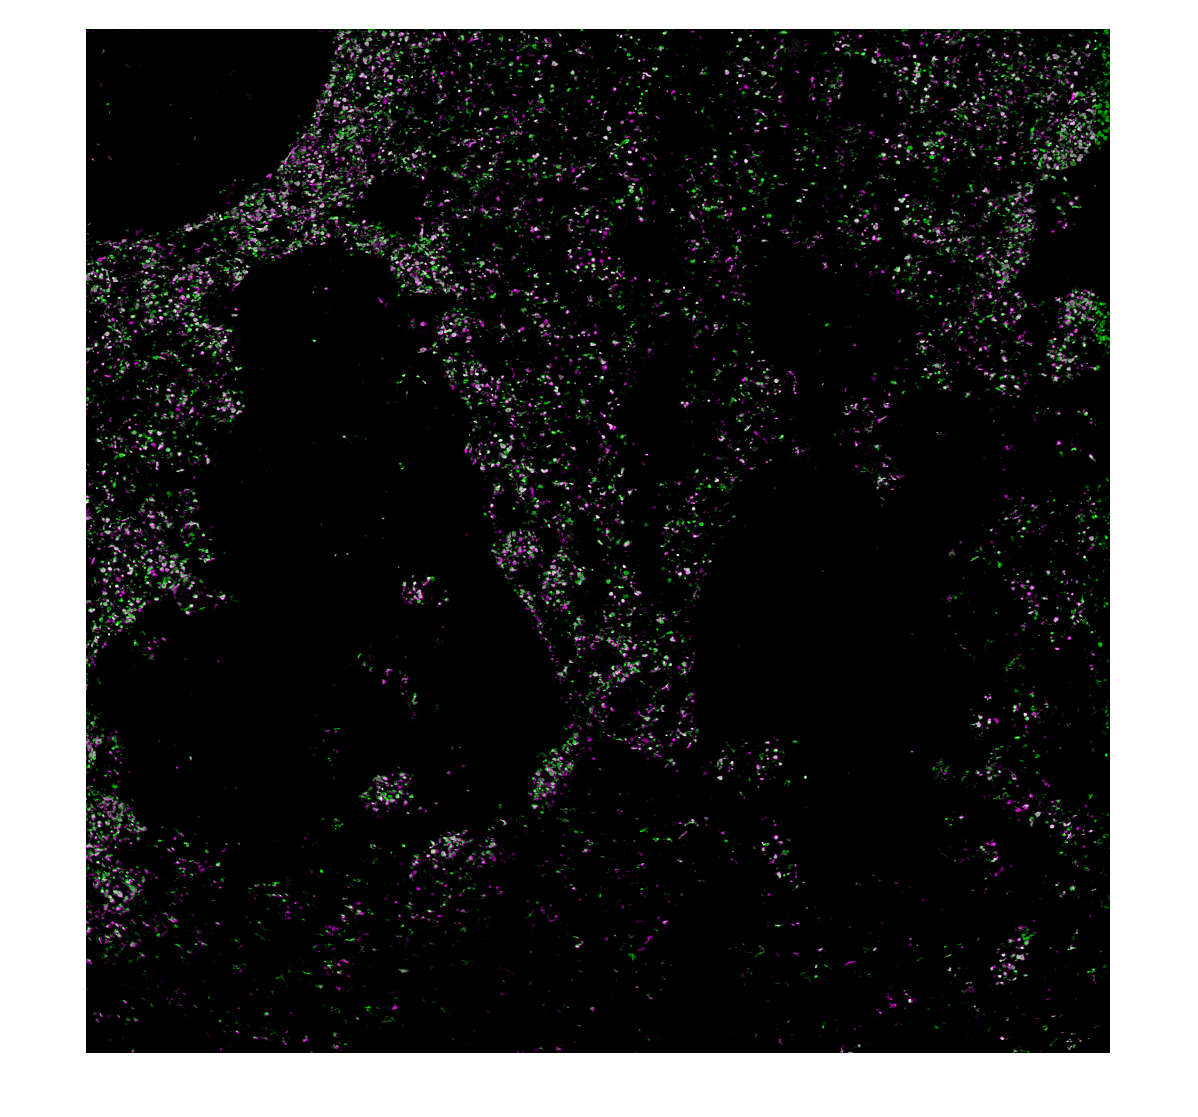

round1 = max(sdata.registeredImages(:,:,:,:,1), [], 4);
% round1_max = max(round1, [], 3);
round1_max = round1(:,:,35);

round2 = max(sdata.registeredImages(:,:,:,:,2), [], 4);
% round2_max = max(round2, [], 3);   
round2_max = round2(:,:,35);

figure
imshowpair(round1_max, round2_max)

figure
imshow(sdata.rawImages(:,:,2,1,1))
figure
imhist(sdata.rawImages(:,:,2,1,1))

sdata = sdata.HistEqualize('Method', "inter_round");
sdata = sdata.HistEqualize('Method', "intra_round");
after = {};
for r=1:5
    for c=1:4
        img = sdata.rawImages(:,:,:,c,r);
        after{end+1} = max(img, [], 3); 
    end
end

figure
montage(after, 'Size', [5 4], "BorderSize", [5 5])

## Spot Finding test

sdata = sdata.LoadCodebook;

====Load Codebook====
doReverse: 1


sdata = sdata.SpotFinding('Method', "max3d", 'qualityThreshold', 0.01, ...
        'volumeThreshold', 1, 'barcodeMethod', "iteration", 'showPlots', true);

====Spot Finding====
Method: max3d
Number of spots found by max3d: 339620
[time = 67.69 s]


sdata = sdata.ReadsExtraction('showPlots', false, 'voxelSize', [1 1 1]); 

====Reads Extraction====
voxel size: 1 x 1 x 1
Geting color sequence for each voxel...

Geting max color...
24485 
Decoding...

0.927905 [315135 / 339620] percent of reads are below score thresh


sdata = sdata.ReadsFiltration('showPlots', false);

====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
0.505878 [159420 / 315135] percent of good reads are CNNNNNC
0.491282 [154820 / 315135] percent of good reads are in codebook
0.971145 [154820 / 159420] percent of CNNNNNC reads are in codebook


img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
img = max(img, [], 3);

plot_centroids(sdata.goodSpots, img, 2)

img = max(sdata.registeredImages(:,:,:,:,1), [], 4);

z=35;
curr_good_points = sdata.goodSpots(sdata.goodSpots(:,3) == z, :);
plot_centroids(curr_good_points, img(:,:,z), 4)

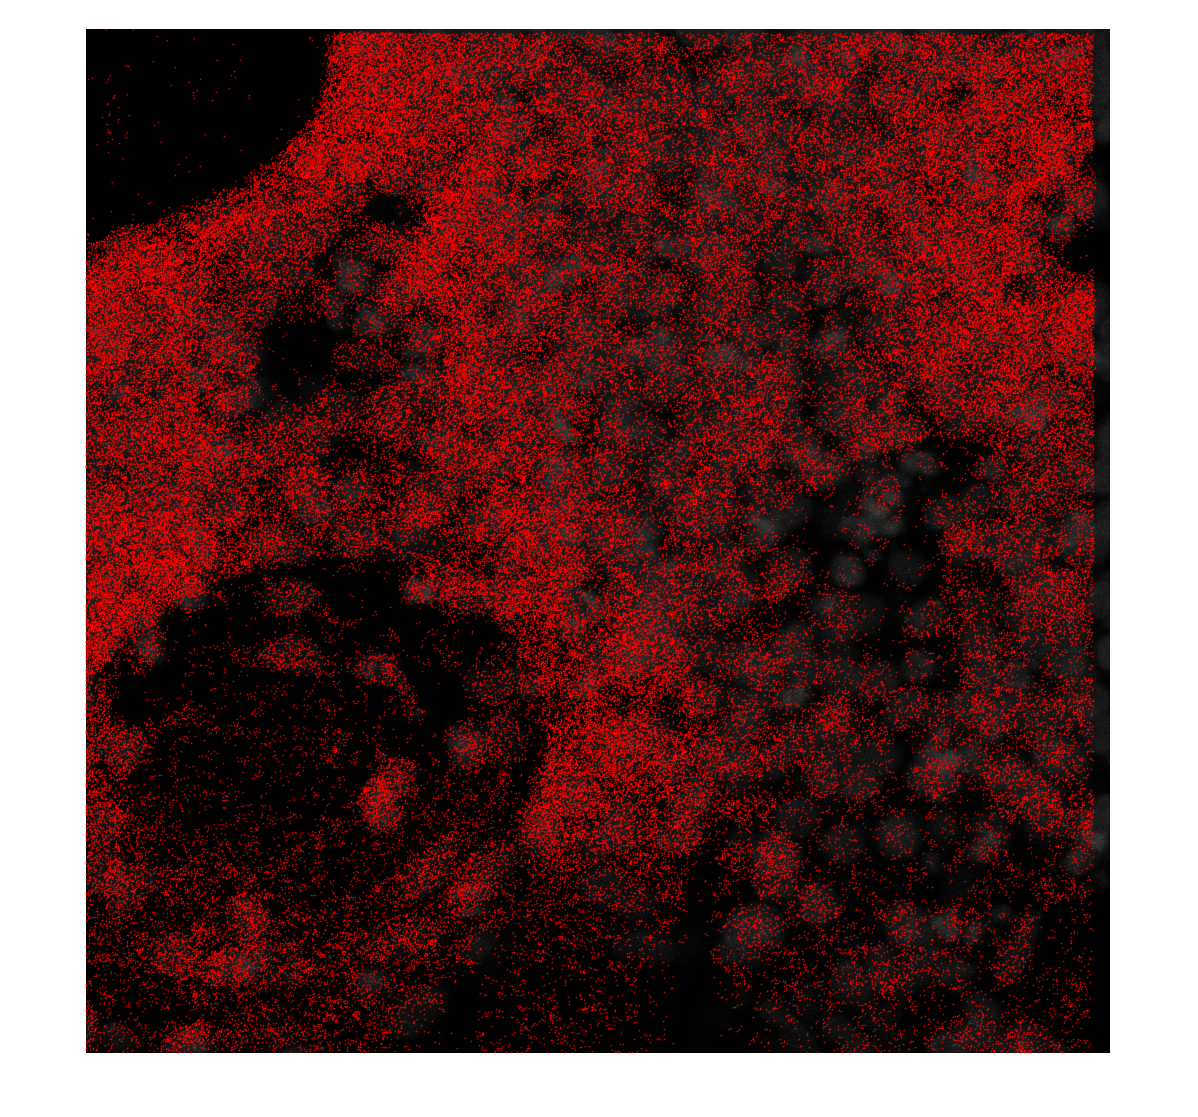

dapi_file = fullfile('F:/2020-09-14-Cardiac-Day21/round1/position1/Mark_and_Find 001_Position001_Lng_z00_ch04.tif');
dapi = new_LoadMultipageTiff(dapi_file, 'uint16', 'uint8', false);
dapi = max(dapi, [], 3);

plot_centroids(sdata.goodSpots, dapi, 2)

img = max(sdata.registeredImages(:,:,:,:,1), [], 4);

for z=1:5
    curr_good_points = sdata.goodSpots(sdata.goodSpots(:,3) == z, :);
    plot_centroids(curr_good_points, img(:,:,z), 5)
end
